% % Goal pose of the robot...
% goalX = 0.52; %5
% goalY = -0.055; %5
% goalZ = 0.66; %5
% 
% % val = max + rand*(max-min)
% 
% 
% goal_X_max_tolarance = goalX +0.01;
% goal_X_min_tolarance = goalX -0.01;
% goal_Y_max_tolarance = goalY +0.01;
% goal_Y_min_tolarance = goalY -0.01;
% goal_Z_max_tolarance = goalY +0.01;
% goal_Z_min_tolarance = goalY -0.01;

% environment interface
mdl = "kinova";
Tfinal = 10;
sampleTime = 0.1;

agentBlk = mdl + "/Agent";

open_system(mdl)

open_system(mdl + "/Environment")


% define observation parameters...
observation=10;
obsInfo = rlNumericSpec([observation 1],...
    "LowerLimit",ones(observation,1),...
    "UpperLimit",ones(observation,1));

numObservations = obsInfo.Dimension(1);
% define action parameters
numActions = 3;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);


% build environment interface
env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.UseFastRestart = "off"

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : kinova
      AgentBlock : kinova/Agent
        ResetFcn : []
  UseFastRestart : off



% SAC agent-critic network 
% critic 1
statePath1 = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(400,'Name','CriticStateFC1')
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(300,'Name','CriticStateFC2')
    ];
actionPath1 = [
    featureInputLayer(numActions,'Normalization','none','Name','action')
    fullyConnectedLayer(300,'Name','CriticActionFC1')
    ];
commonPath1 = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1,'Name','CriticOutput')
    ];

criticNet1 = layerGraph(statePath1);
criticNet1 = addLayers(criticNet1,actionPath1);
criticNet1 = addLayers(criticNet1,commonPath1);
criticNet1 = connectLayers(criticNet1,'CriticStateFC2','add/in1');
criticNet1 = connectLayers(criticNet1,'CriticActionFC1','add/in2');


%critic 2
statePath2 = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','CriticStateFC1')
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(64,'Name','CriticStateFC2')
    ];
actionPath2 = [
    featureInputLayer(numActions,'Normalization','none','Name','action')
    fullyConnectedLayer(64,'Name','CriticActionFC1')
    ];
commonPath2 = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1,'Name','CriticOutput')
    ];

criticNet2 = layerGraph(statePath2);
criticNet2 = addLayers(criticNet2,actionPath2);
criticNet2 = addLayers(criticNet2,commonPath2);
criticNet2 = connectLayers(criticNet2,'CriticStateFC2','add/in1');
criticNet2 = connectLayers(criticNet2,'CriticActionFC1','add/in2');


% create  critic using rlRepresentation

criticOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-3,... 
                                        'GradientThreshold',1,'L2RegularizationFactor',2e-4)

criticOptions =   rlRepresentationOptions with properties:

                  LearnRate: 1.0000e-03
          GradientThreshold: 1
    GradientThresholdMethod: "l2norm"
     L2RegularizationFactor: 2.0000e-04
                  UseDevice: "cpu"
                  Optimizer: "adam"
        OptimizerParameters: [1×1 rl.option.OptimizerParameters]


critic1 = rlQValueRepresentation(criticNet1,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);
critic2 = rlQValueRepresentation(criticNet2,obsInfo,actInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);

% create actor
statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(400, 'Name','commonFC1')
    reluLayer('Name','CommonRelu')];
meanPath = [
    fullyConnectedLayer(300,'Name','MeanFC1')
    reluLayer('Name','MeanRelu')
    fullyConnectedLayer(numActions,'Name','Mean')
    ];
stdPath = [
    fullyConnectedLayer(300,'Name','StdFC1')
    reluLayer('Name','StdRelu')
    fullyConnectedLayer(numActions,'Name','StdFC2')
    softplusLayer('Name','StandardDeviation')
    ];

concatPath = [
    concatenationLayer(1,2,'Name','GaussianParameters')
    tanhLayer('Name','tanh')
    scalingLayer('Name','Scaling','Scale',actInfo.UpperLimit)
%     scalingLayer('Name','StandardDeviation')
    ];

actorNetwork = layerGraph(statePath);
actorNetwork = addLayers(actorNetwork,meanPath);
actorNetwork = addLayers(actorNetwork,stdPath);
actorNetwork = addLayers(actorNetwork,concatPath);
actorNetwork = connectLayers(actorNetwork,'CommonRelu','MeanFC1/in');
actorNetwork = connectLayers(actorNetwork,'CommonRelu','StdFC1/in');
actorNetwork = connectLayers(actorNetwork,'Mean','GaussianParameters/in1');
actorNetwork = connectLayers(actorNetwork,'StandardDeviation','GaussianParameters/in2');


% create Stochastic actor representation
actorOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-3,...
                                       'GradientThreshold',1,'L2RegularizationFactor',1e-5);

actor = rlStochasticActorRepresentation(actorNetwork,obsInfo,actInfo,actorOptions,...
    'Observation',{'observation'});


% create SAC agent
SampleTime = 0.1

SampleTime = 0.1000

agentOptions = rlSACAgentOptions;
agentOptions.SampleTime = SampleTime;
agentOptions.EntropyWeightOptions.EntropyWeight = 0.1; 
% agentOptions.EntropyWeightOptions.LearnRate = 0;
agentOptions.PolicyUpdateFrequency = 1;
agentOptions.CriticUpdateFrequency = 1;
agentOptions.DiscountFactor = 0.99;
agentOptions.TargetSmoothFactor = 1e-3;
agentOptions.ExperienceBufferLength = 1e5;
agentOptions.MiniBatchSize = 256; %128;
agentOptions.NumStepsToLookAhead = 3;
agentOptions.SaveExperienceBufferWithAgent =true;
agentOptions.ResetExperienceBufferBeforeTraining = false;
%agentOpts.NoiseOptions.Variance = 0.1;
%agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;
%% Create SAC agent using actor, critics, and options


agentOptions =   rlSACAgentOptions with properties:

                   EntropyWeightOptions: [1×1 rl.option.EntropyWeightOptions]
                  PolicyUpdateFrequency: 1
                  CriticUpdateFrequency: 1
                      NumWarmStartSteps: 64
              NumGradientStepsPerUpdate: 1
           UseDeterministicExploitation: 0
                     TargetSmoothFactor: 1.0000e-03
                  TargetUpdateFrequency: 1
    ResetExperienceBufferBeforeTraining: 0
          SaveExperienceBufferWithAgent: 1
                         SequenceLength: 1
                          MiniBatchSize: 256
                    NumStepsToLookAhead: 3
                 ExperienceBufferLength: 100000
                             SampleTime: 0.1000
                         DiscountFactor: 0.9900


Agent = rlSACAgent(actor,[criagentOptionstic1 critic2],agentOptions);
open_system(mdl + "/Agent")


% train agent..............
maxEpisodes = 1000;
maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",20000, ...
    "Verbose", true, ...
    "Plots","training-progress");
trainOpts.SaveAgentCriteria = "EpisodeReward";
trainOpts.SaveAgentValue = 270;

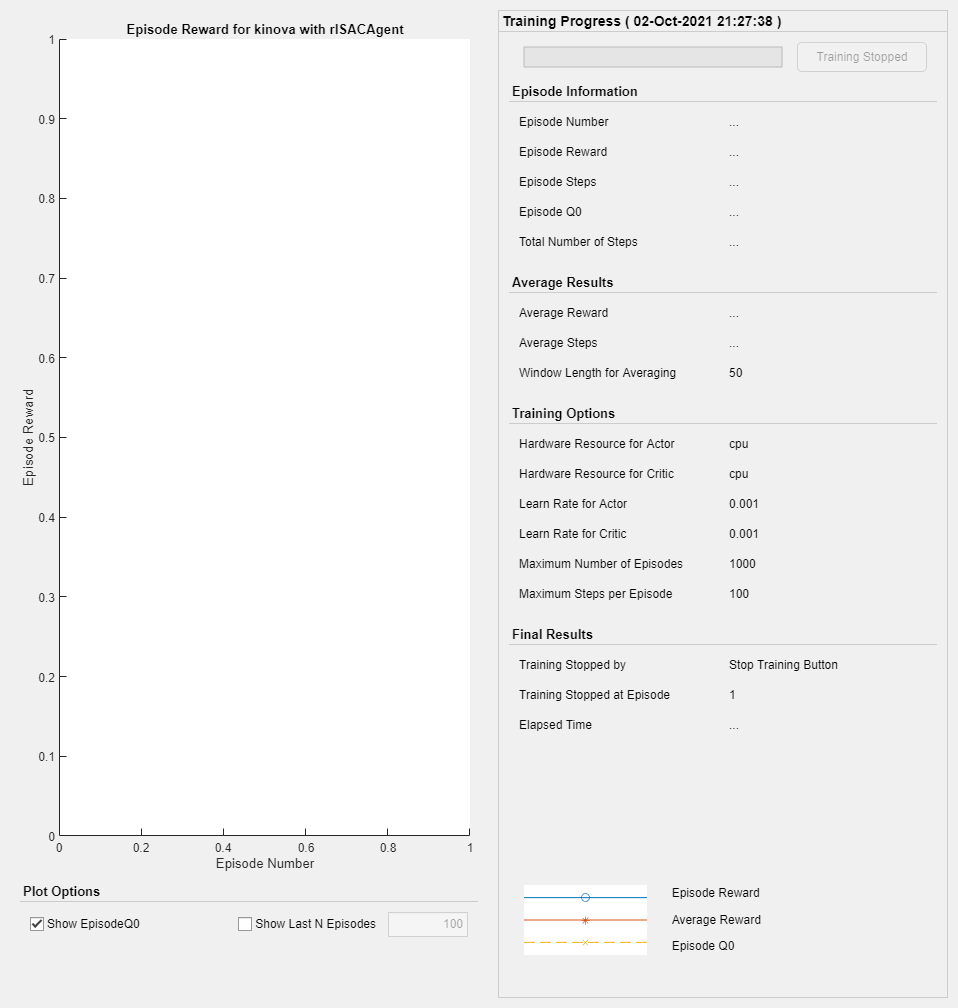


% doTraining...........................
doTraining = true; %false; %true; % Toggle this to true for training 

if doTraining
%     load ('i01new.mat', 'Agent')
    % Train the agent.
    trainingStats = train(Agent,env,trainOpts);
    save ('TrainAgent.mat','Agent');
else
    % Load pretrained agent for the example.
    rng(0);
    load ('TrainAgent.mat', 'Agent')
    simOptions = rlSimulationOptions('MaxSteps',maxSteps);
    experience = sim(env,Agent,simOptions);

end
